### Exercise 7

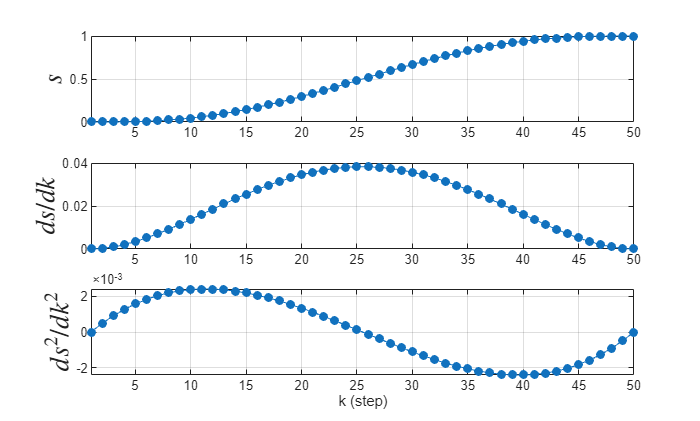

tpoly(0, 1, 50);

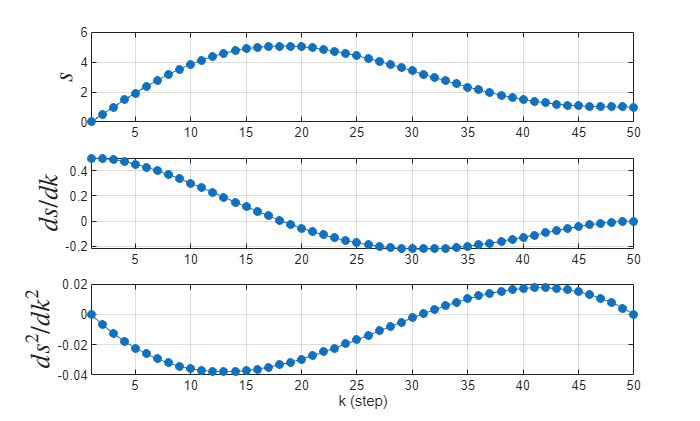

[s,sd,sdd] = tpoly(0, 1, 50);



tpoly(0, 1, 50, 0.5, 0);

v_i=0.5, v_f=0

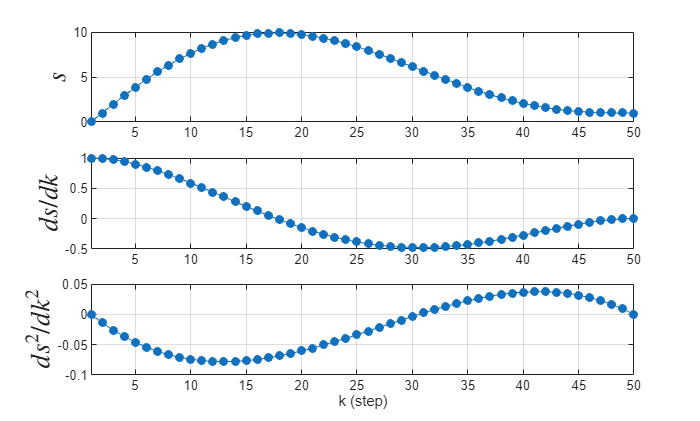

tpoly(0, 1, 50, 1, 0);

v_i=1, v_f=0

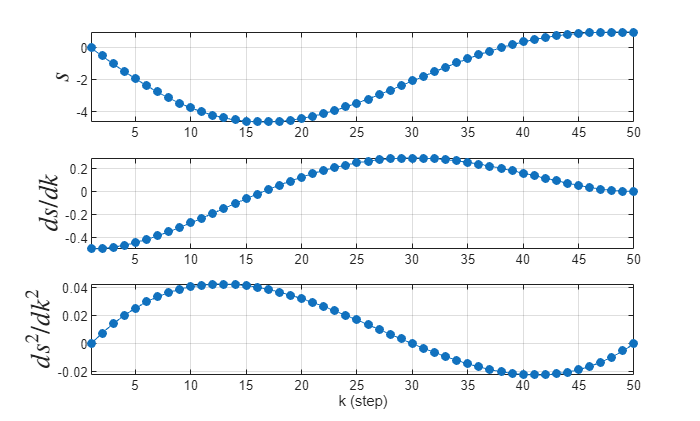

tpoly(0, 1, 50, -0.5, 0);

v_i=-0.5, v_f=0

### Exersice 8

mean(sd) / max(sd)

ans = 0.5000

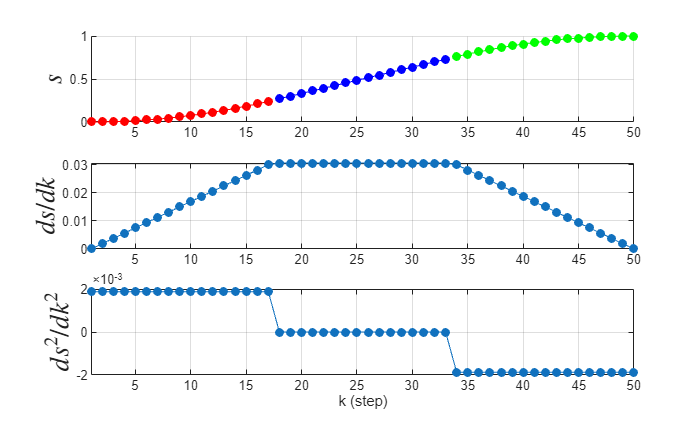



lspb(0, 1, 50);

[s,sd,sdd] = lspb(0, 1, 50);
max(sd)

ans = 0.0306

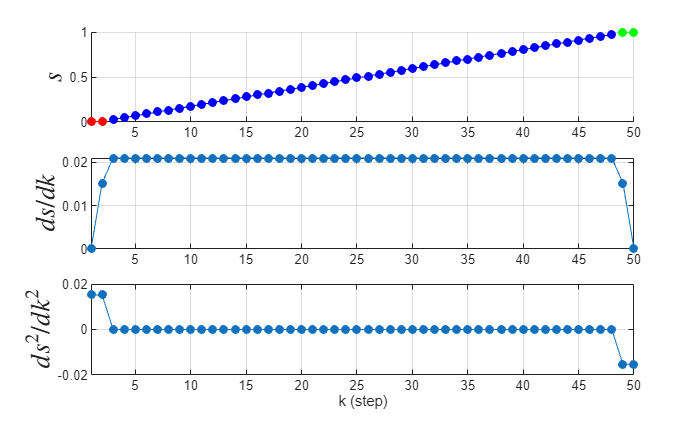

lspb(0, 1, 50, 0.021)

[s,sd,sdd]=lspb(0, 1, 50, 0.021);
max(sd)

ans = 0.0210

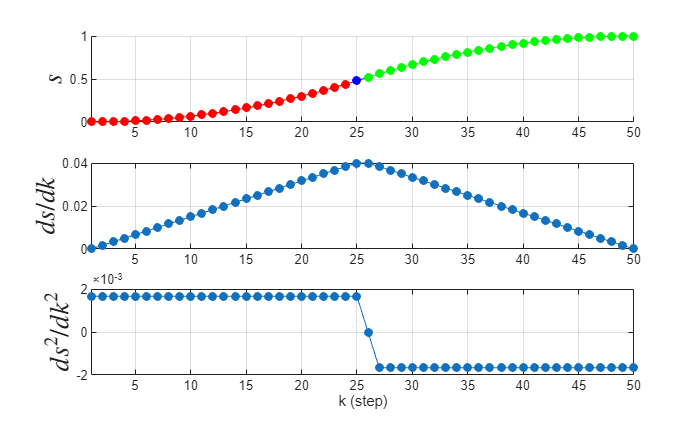

lspb(0, 1, 50, 0.040)

[s,sd,sdd]=lspb(0, 1, 50, 0.040);
max(sd)

ans = 0.0400

### Exersice 9

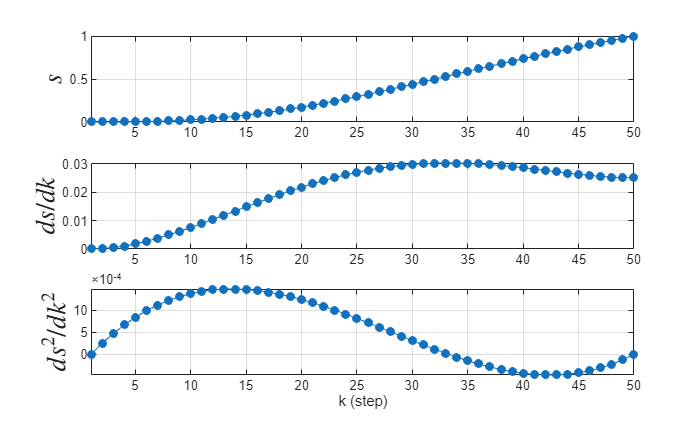

tpoly(0, 1, 50, 0, 0.025);

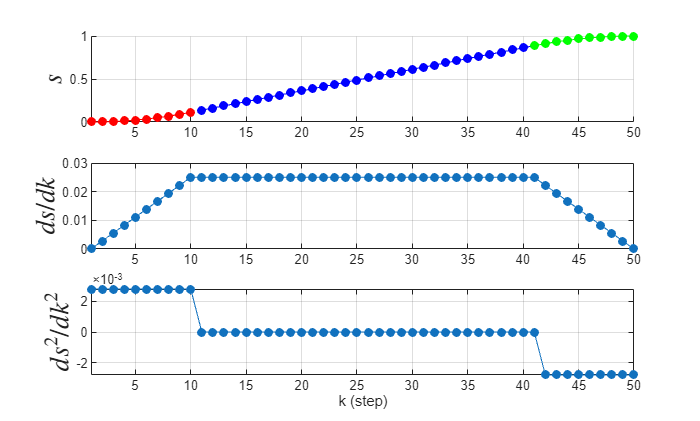

lspb(0, 1, 50, 0.025);

### Exersice 13

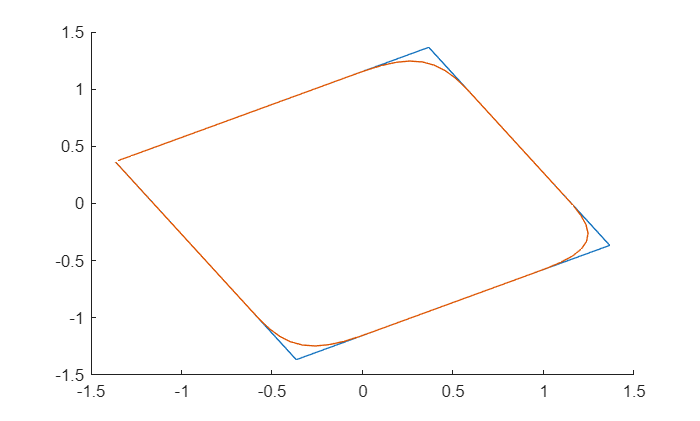

clf

via = SO2(30, 'deg') * [-1 1; 1 1; 1 -1; -1 -1]';
hold on
q0 = mstraj(via(:,[2 3 4 1])', [1,8], [], via(:,1)', 0.2, 0);
plot(q0(:,1), q0(:,2))
q1 = mstraj(via(:,[2 3 4 1])', [2,1], [], via(:,1)', 0.2, 2);
plot(q1(:,1), q1(:,2))

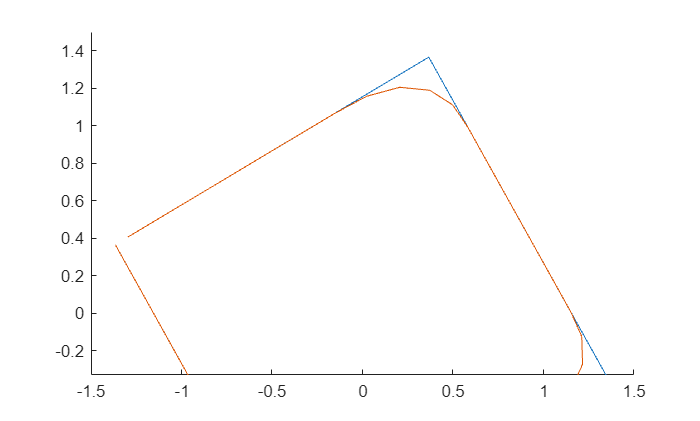


clf

via = SO2(30, 'deg') * [-1 1; 1 1; 1 -1; -1 -1]';
hold on
q0 = mstraj(via(:,[2 3 4 1])', [2,1], [], via(:,1)', 0.2, 0);
q1 = mstraj(via(:,[2 3 4 1])', [2,1], [], via(:,1)', 0.2, 1);
plot(q0(:,1), q0(:,2))
plot(q1(:,1), q1(:,2))


q2 = mstraj(via(:,[2 3 4 1])', [2,1], [], via(:,1)', 0.2, 2);

[numrows(q0) numrows(q2)]

ans =     28    80


## LAB 

### TASK 3.1

A=[0 0 0;0 0 0]

A =      0     0     0
     0     0     0


B=[0 0 1;0 pi/2 0]

B =          0         0    1.0000
         0    1.5708         0


C=[1 0 1;0 -pi 0]

C =     1.0000         0    1.0000
         0   -3.1416         0


D=[1 0 -0.5; 0 pi/2 0]

D =     1.0000         0   -0.5000
         0    1.5708         0


clf

via =  [A(1,:) A(2,:) ; B(1,:) B(2,:) ; C(1,:) C(2,:);D(1,:) D(2,:)]';
via(:,1)'

ans =      0     0     0     0     0     0


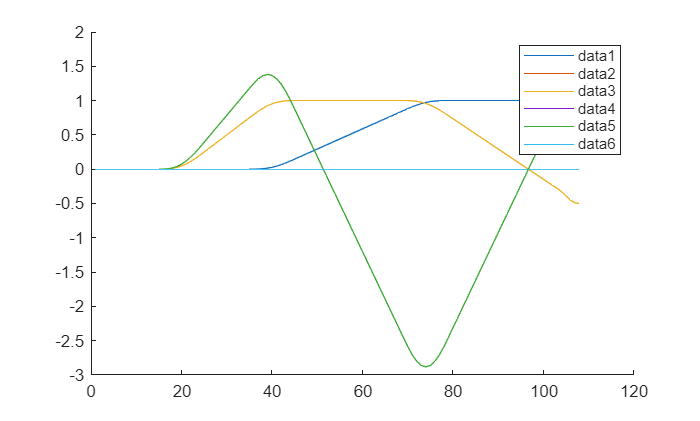

hold on
q0 = mstraj(via(:,[1 2 3 4])', [2,2,2,1,1,1], [], via(:,1)', 0.2, 2);
plot(q0);
legend

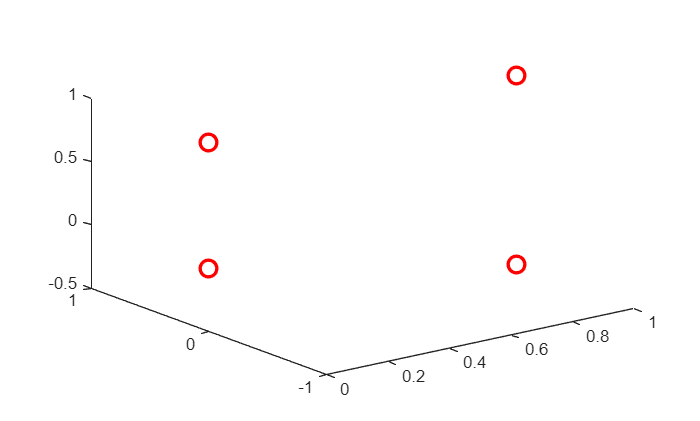


figure
Ts= SE3.empty();
for i =(1:1:length(q0(:,1)))
    Ts(i)=SE3([q0(i,1), q0(i,2),q0(i,3)]) * SE3.rpy(q0(i,4), q0(i,5), q0(i,6));
end

target_points = [A(1,:);B(1,:);C(1,:);D(1,:)]; 
plot3(target_points(:,1), target_points(:,2), target_points(:,3), 'ro', 'MarkerSize', 10, 'LineWidth', 2);

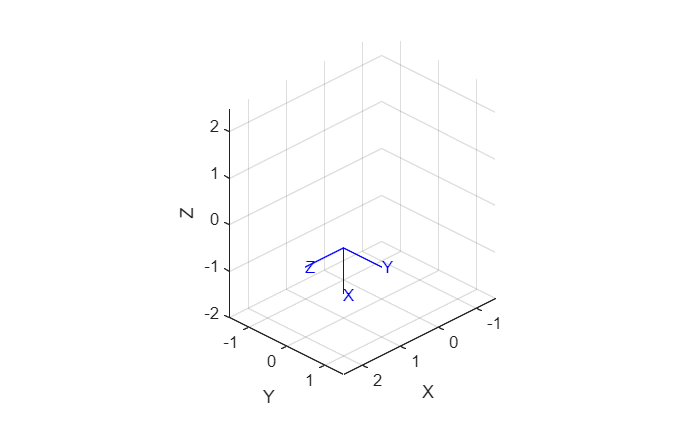


tranimate(Ts, 'view', [135, 30], 'dims', [-2 5 -2 5 -2 5])

Ts.animate

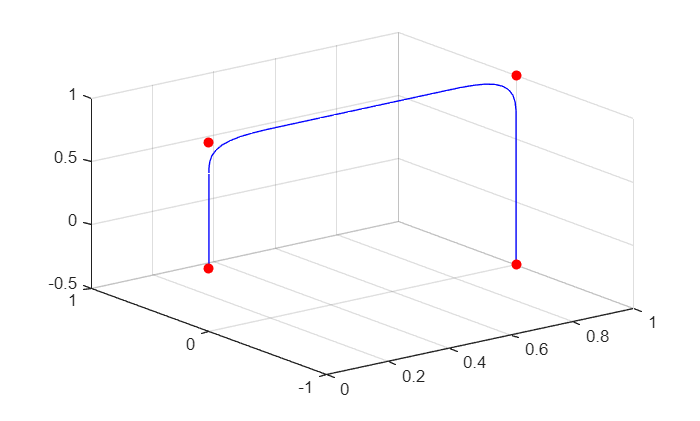

figure
plot3(q0(:,1), q0(:,2), q0(:,3), "-", Color="b")  % plot3 line
hold on                                            % retain existing plot
scatter3(A(1,1), A(1,2), A(1,3), 36, "r", "filled") % visible red dot
scatter3(B(1,1),B(1,2), B(1,3), 36, "r", "filled")
scatter3(C(1,1), C(1,2), C(1,3), 36, "r", "filled")
scatter3(D(1,1), D(1,2), D(1,3), 36, "r", "filled")
hold off
grid on
view(3)

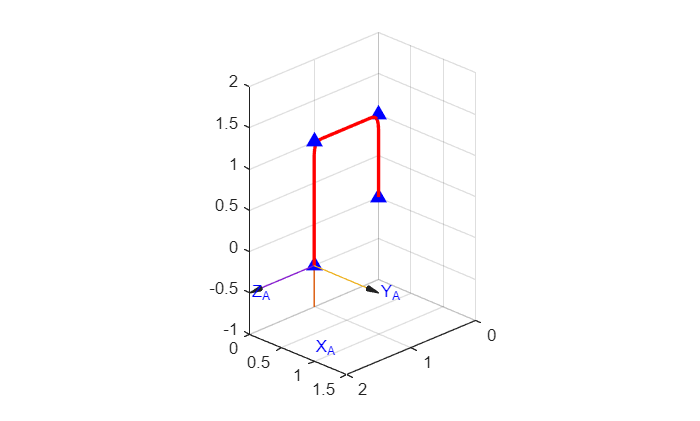


path_positions = Ts.t; 


figure;
hold on;
grid on;
view(135, 25);           
axis([0 2 0 1.5 -1 2]);   


waypoints = [A(1,:);B(1,:);C(1,:);D(1,:)];
plot3(waypoints(:,1), waypoints(:,2), waypoints(:,3), 'b^', 'MarkerFaceColor', 'b', 'MarkerSize', 8);
plot3(q0(:,1), q0(:,2), q0(:,3), 'r-', 'LineWidth', 2); 

hFrame = [];


for i = 1:length(Ts)
    
   
    if ~isempty(hFrame)
        delete(hFrame); 
    end
    
   
      
    hFrame = Ts(i).plot('frame', 'A', 'arrow', 'b', 'b'); 
    drawnow;
    pause(0.04); 
end

### TASK 3.2

%% clear the workspace variables and close all figures
clear all
clc
close all
%% Load the map
load map1
about map

map [double] : 100x100 (80.0 kB)


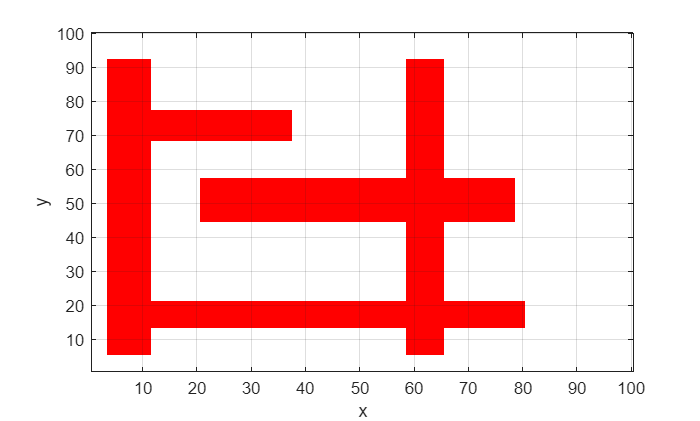

line =     80    50
   100    50


flag = logical
   0


flag = logical
   1


flag = logical
   0


flag = logical
   1


flag = logical
   0


flag = logical
   1


flag = logical
   0


flag = logical
   1


flag = logical
   0


flag = logical
   1


flag = logical
   0


flag = logical
   1


flag = logical
   0


flag = logical
   1


flag = logical
   0


flag = logical
   1


flag = logical
   0


flag = logical
   1


flag = logical
   0


flag = logical
   1


flag = logical
   0


flag = logical
   1


flag = logical
   0


flag = logical
   1


flag = logical
   0


flag = logical
   1


flag = logical
   0


flag = logical
   1


flag = logical
   0


flag = logical
   1


flag = logical
   0


flag = logical
   1


flag = logical
   0


flag = logical
   1


flag = logical
   0


flag = logical
   1


flag = logical
   0


flag = logical
   1


flag = logical
   0


flag = logical
   1


flag = logical
   0


flag = logical
   1


flag = logical
   0


flag = logical
   1


flag = logical
   0


flag = logical
   1


flag = logical
   0


flag = logical
   1


flag = logical
   0


flag = logical
   1


%% plot the map
plot(Bug2(map))
%% Initial position and heading of the robot
p_init=[50 30]; % [x,y]
%% Goal location of the robot 
p_goal=[20 5]; % [x,y]

%% Define the desired path 
path=[ p_init;
       15 30 ;
       15 65 ;
       50 65 ;
       50 100 ;
       90 100 ;
       90 60;
       95 60;
       90 0 ;
       50 0;
       50 10;
       20 10 ;
       p_goal
    ];

 
%% Genrate trajectory
TIME=[20,20,20,20,20,20,20,10,20,20,20,20,20]; %axis speed limits
Q0= path(1,:); %initial axis coordinates
DT=0.2;
traj = mstraj(path, [], TIME, Q0, DT, 10);

%% Plot the path
%plot(traj);
obstacle=1; %0 when there is no door to block the way, 1 the door will be on
animatepath(traj,DT,obstacle)